clearvars
close all

addpath("./kd-tree")
tests=struct('dir',"",'filename',"",'delimiter','','dimension',0,'NClusters',0,...
             'distType',0,'minPts',[],'eps',[],'eps2',[],'linePars',[]);
tests=createTests();
%select test data
test=tests(8);
%select algorithm: true=parallelized version, false=kd-tree version
preCalc=true;
tic
analyzer=ClusterAnalyzer(test.distType,preCalc);
analyzer.loadDataSet(fullfile(test.dir,test.filename),test.delimiter,test.dimension);
toc

Elapsed time is 1.346457 seconds.


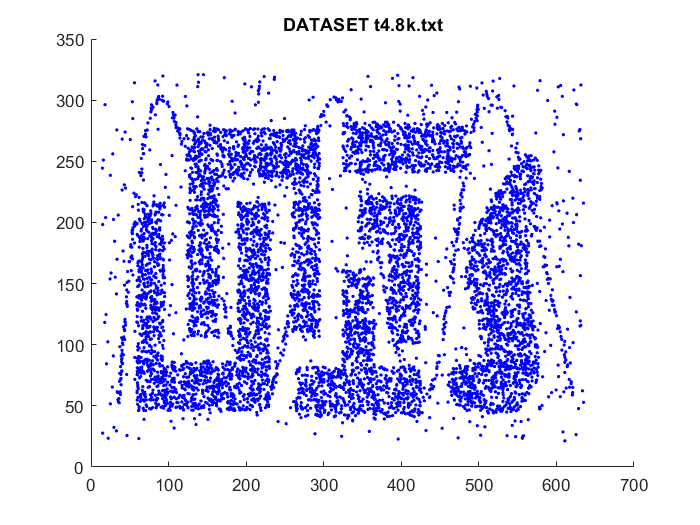

figure(1)
scatter(analyzer.rawData(:,1),analyzer.rawData(:,2),'blue','.')
title(sprintf('DATASET %s',test.filename))

kDistance=zeros(analyzer.NPoints,length(test.minPts));
for i=1:length(test.minPts)
    %@(Xi,Xj) analyzer.pdist(Xi,Xj,analyzer.distType)
  d = pdist2(analyzer.rawData,analyzer.rawData, ...
      'euclidean','Smallest',test.minPts(i)); % The minpts smallest pairwise distances
  kDistance(:,i)=sort(d(end,:))';
end

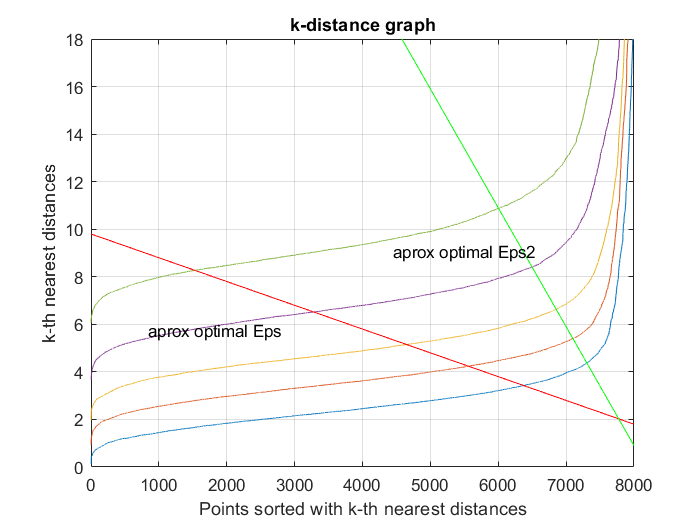

meps=@(x) (x-double(analyzer.NPoints))*-test.linePars(1)+test.linePars(2);
meps2=@(x) (x-double(analyzer.NPoints))*-test.linePars(3)+test.linePars(4);

figure(2)
%% k-distance graph
plot(kDistance);
hold on
dt=0.1;
%plot(eps.*(ones(analyzer.NPoints,1)),'Color','red')
plot((1:dt:double(analyzer.NPoints)),meps(1:dt:double(analyzer.NPoints)),'Color','red')
annotation('textbox',[0.2 0.35 0.25 0.05],'String','aprox optimal Eps','LineStyle','none')

plot((1:dt:double(analyzer.NPoints)),meps2(1:dt:double(analyzer.NPoints)),'Color','green')
annotation('textbox',[0.55 0.5 0.25 0.05],'String','aprox optimal Eps2','LineStyle','none')

title('k-distance graph')
xlabel('Points sorted with k-th nearest distances')
ylabel('k-th nearest distances')
xlim([0,analyzer.NPoints])
if test.dir=="./t1"
    ylim([0 18])
end
if test.filename=="Aggregation.txt"    
    xlim([600,analyzer.NPoints])
end
if test.filename=="flame.txt"    
    xlim([200,analyzer.NPoints])
end
if test.filename=="D31.txt"    
    ylim([0 5])
    xlim([2000,analyzer.NPoints])
end
if test.filename=="cure-t2-4k.txt" 
    ylim([0 0.5])    
    xlim([2500,analyzer.NPoints])
end
hold off
grid

clusters=zeros(analyzer.NPoints,2*length(test.minPts));
timeEl=zeros(2*length(test.minPts),1);
for i=1:length(test.minPts)
    tic
    clusters(:,i)=analyzer.mDBScan(test.eps(i),test.minPts(i));
    disp(["done ",i," 1st"]);
    timeEl(i*2-1)=toc;
    tic
    clusters(:,length(test.minPts)+i)=analyzer.mDBScan(test.eps2(i),test.minPts(i));
    disp(["done ",i," 2nd"]);
    timeEl(i*2)=toc;
end

    "done "    "1"    " 1st"



    "done "    "1"    " 2nd"



    "done "    "2"    " 1st"



    "done "    "2"    " 2nd"



    "done "    "3"    " 1st"



    "done "    "3"    " 2nd"



    "done "    "4"    " 1st"



    "done "    "4"    " 2nd"



    "done "    "5"    " 1st"



    "done "    "5"    " 2nd"



disp(timeEl);

    0.5411
    0.4113
    0.3263
    0.3070
    0.2532
    0.2697
    0.2011
    0.2476
    0.1388
    0.2556



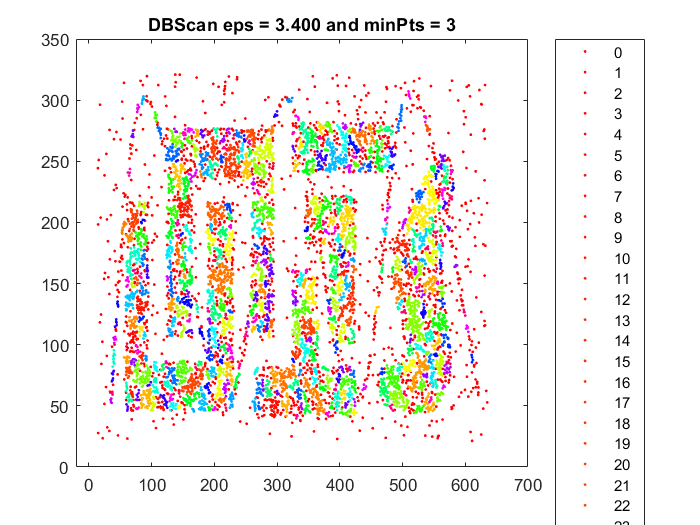

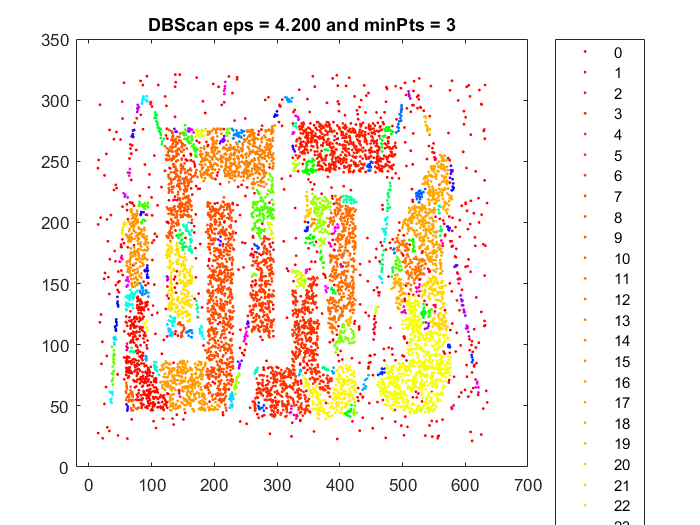

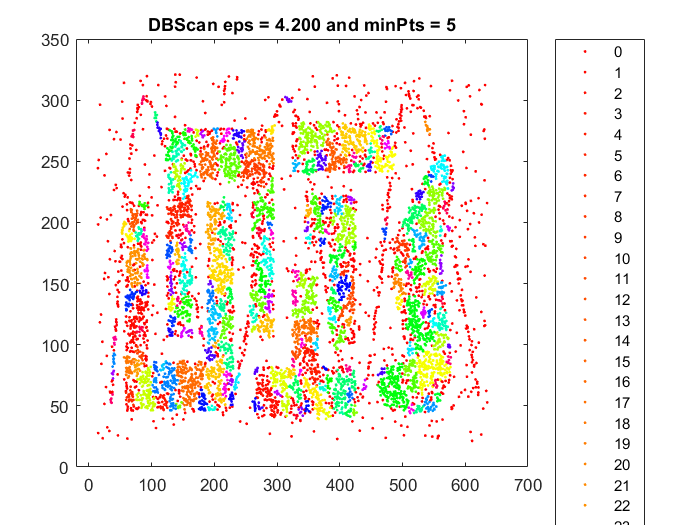

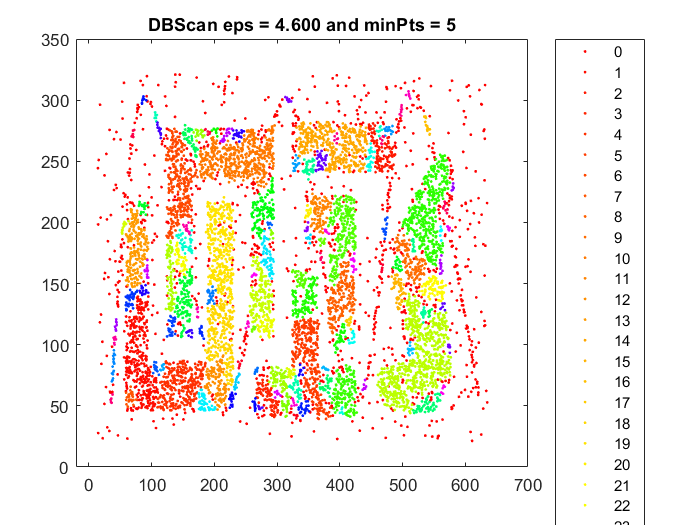

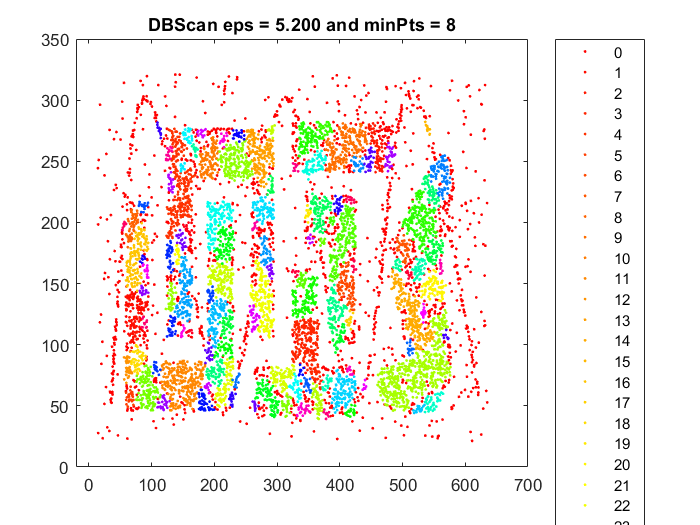

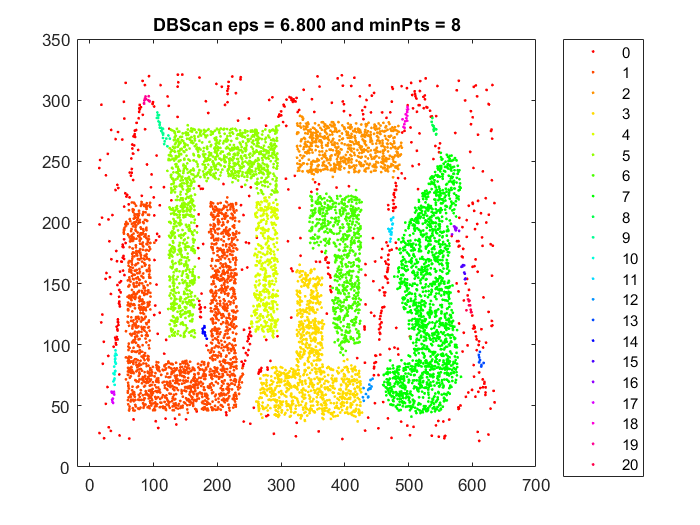

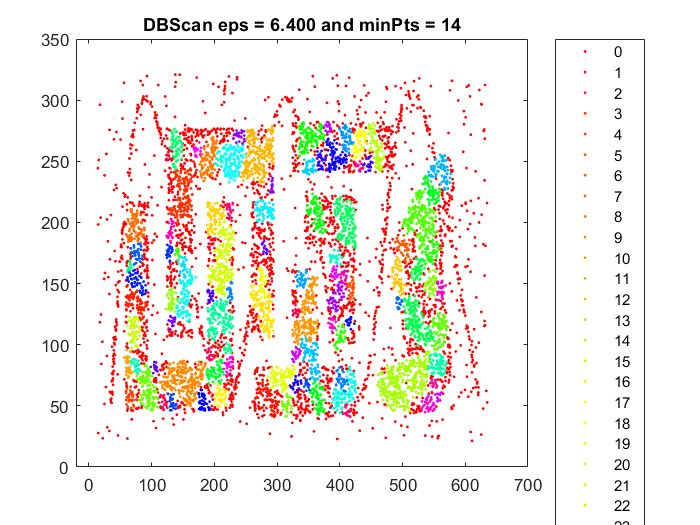

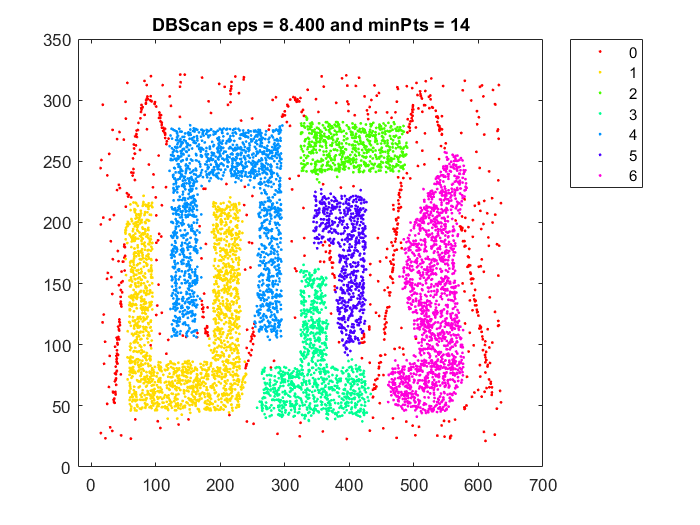

 for idx=1:length(test.minPts)
    figure(30+idx)
    %subplot(1,2,1)
    gscatter(analyzer.rawData(:,1),analyzer.rawData(:,2),clusters(:,idx))
    title(sprintf('DBScan eps = %.3f and minPts = %d',test.eps(idx),test.minPts(idx)))
    legend('Location','northeastoutside')
    figure(40+idx)
    %subplot(1,2,2)
    gscatter(analyzer.rawData(:,1),analyzer.rawData(:,2),clusters(:,length(test.minPts)+idx))
    title(sprintf('DBScan eps = %.3f and minPts = %d',test.eps2(idx),test.minPts(idx)))
    legend('Location','northeastoutside')
    %fullfig(10+idx)           
end

if(analyzer.hasControl)
    figure(19)
    gscatter(analyzer.rawData(:,1),analyzer.rawData(:,2),analyzer.controlClustering)
    title(sprintf('DBScan control Clustering'))
    legend('Location','northeastoutside')
end

tic
clustDB=dbscan(analyzer.rawData,test.eps2(1),test.minPts(1));
toc

Elapsed time is 0.350210 seconds.


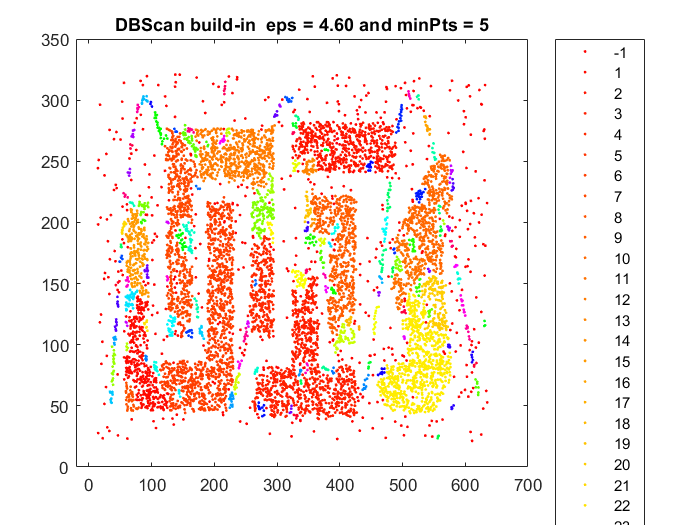

figure(20)
gscatter(analyzer.rawData(:,1),analyzer.rawData(:,2),clustDB)
title(sprintf('DBScan build-in  eps = %.2f and minPts = %d',test.eps2(2),test.minPts(2)))
legend('Location','northeastoutside')

tic
[clustMeans,centroids]=kmeans(analyzer.rawData,test.NClusters); %default is kmeans++ (uniform choise for first center)
toc

Elapsed time is 0.109346 seconds.


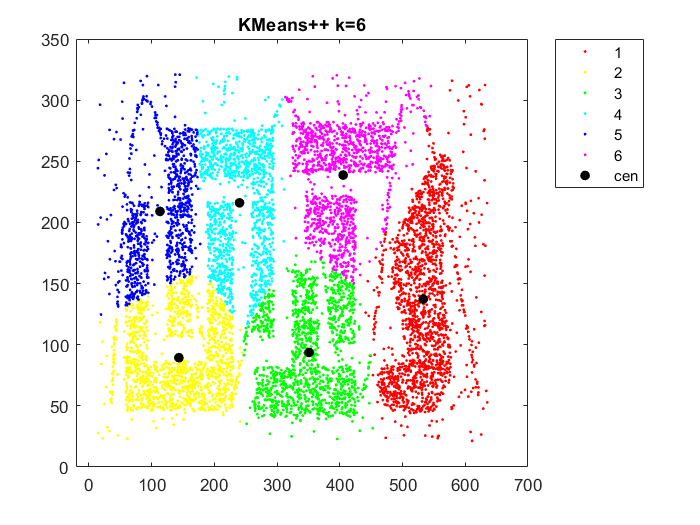

figure(21)

gscatter(analyzer.rawData(:,1),analyzer.rawData(:,2),clustMeans)
hold on
plot(centroids(:,1),centroids(:,2),'.','MarkerSize',20,"Color","black","DisplayName","cen")
title(sprintf('KMeans++ k=%i',test.NClusters))
hold off
legend('Location','northeastoutside')